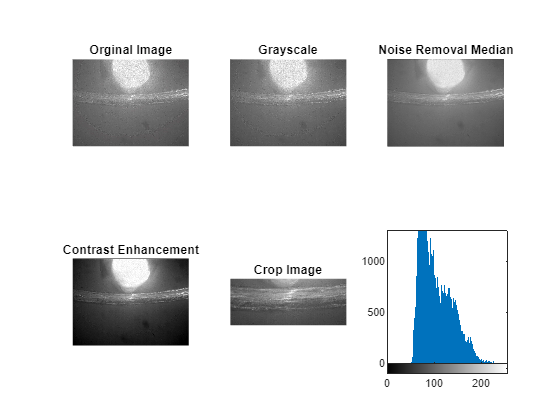

% Read and convert to gray img
[fileName, pathName] = uigetfile('*.*');
I = importdata([pathName, fileName]);
Igray = rgb2gray(I);
subplot(2,3,1), imshow(I), title('Orginal Image');
subplot(2,3,2), imshow(Igray),title('Grayscale');
 
% Noise Removal
Kmedian = medfilt2(Igray);
subplot(2,3,3), imshow(Kmedian), title('Noise Removal Median');

% Contrast
Contrast = imadjust(Kmedian);
subplot(2,3,4), imshow(Contrast), title('Contrast Enhancement');

% Crop
CropIm = imcrop(Contrast,[200 210 400 160]);
subplot(2,3,5), imshow(CropIm), title('Crop Image');
subplot(2,3,6), imhist(CropIm);